# Workflow DES + Agua

**1. Importar los datos de densidad**

Dens_Eth=readtable("TFM\DATASET_TFM_DES_H2O.xlsx","Sheet","Dens_Ethaline","VariableNamingRule","preserve")

Dens_Eth = 260×10 table
        DES            Set Type           Mixture       Mass_percent_Water    Mass_percent_DES    Temperature(K)    Density(kg.m-3)    Density(g.cm-3)        Reference         DES mole fraction
    ___________    ________________    _____________    __________________    ________________    ______________    _______________    _______________    __________________    _________________

    {'ChCl-EG'}    {'Computed'    }    {'DES+Water'}              0                    1              303.15            1116.9             1.1169         {'(Celebi, 2019)'}           NaN       
    {'ChCl-EG'}    {'Computed'    }    {'DES+Water'} 

Gráfica de datos de densidad

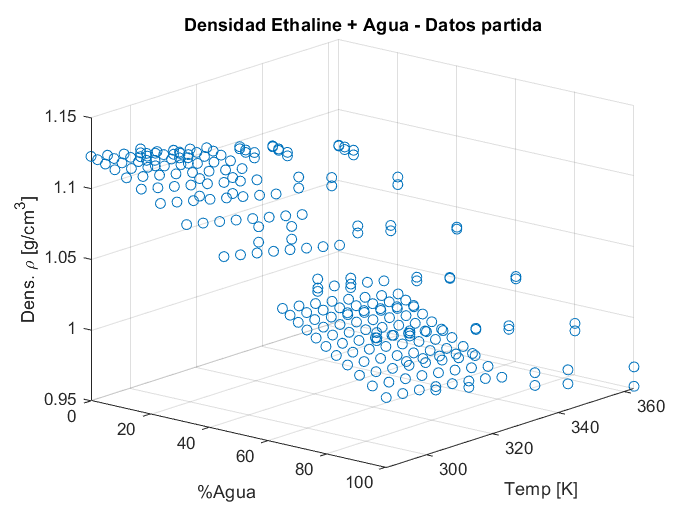

Masa_H2O_Eth=Dens_Eth.Mass_percent_Water*100;
Temp_Eth=Dens_Eth.("Temperature(K)");
Rho_Eth=Dens_Eth.("Density(g.cm-3)");
figure, plot3(Masa_H2O_Eth,Temp_Eth,Rho_Eth,'o');
title('Densidad Ethaline + Agua - Datos partida'), grid on,
xlabel('%Agua'), ylabel('Temp [K]'), zlabel('Dens. \rho [g/cm^3]'),
view([40 20])

**2. División Conjuntos de Datos Entrenamiento y Prueba**

Matriz de datos de entrenamiento

data1=[Masa_H2O_Eth,Temp_Eth,Rho_Eth];
n=length(data1);
particion=cvpartition(n,'HoldOut',0.2) % Se separa un 20% de datos para prueba

particion = Hold-out cross validation partition
   NumObservations: 260
       NumTestSets: 1
         TrainSize: 208
          TestSize: 52

Datos de entrenamiento

idx_train=training(particion);
train_data_dens1=data1(idx_train,:)

train_data_dens1 =          0  303.1500    1.1169
         0  313.1500    1.1086
         0  333.1500    1.0962
         0  343.1500    1.0893
         0  363.1500    1.0749
         0  303.1500    1.1114
         0  333.1500    1.0947
         0  343.1500    1.0887
    2.0000  303.1500    1.1147
    2.0000  313.1500    1.1082



Masa_H2O_Eth_train=train_data_dens1(:,1);
Temp_Eth_train=train_data_dens1(:,2);
Rho_Eth_train=train_data_dens1(:,3);

Datos de prueba

idx_test=test(particion);
test_data_dens1=data1(idx_test,:)

test_data_dens1 =          0  313.1500    1.1057
         0  363.1500    1.0744
    5.0000  303.1500    1.1162
    5.0000  303.1500    1.1073
    5.0000  313.1500    1.1016
   20.0000  303.1500    1.1053
   20.0000  343.1500    1.0763
   20.0000  303.1500    1.0929
   20.0000  343.1500    1.0704
   40.0000  333.1500    1.0589



Masa_H2O_Eth_test=test_data_dens1(:,1);
Temp_Eth_test=test_data_dens1(:,2);
Rho_Eth_test=test_data_dens1(:,3);

**3. Regresión**

predictores_train=[Masa_H2O_Eth_train Temp_Eth_train];
regresion1 = fitlm(predictores_train,Rho_Eth_train)

regresion1 = Linear regression model:
    y ~ 1 + x1 + x2

Estimated Coefficients:
                    Estimate         SE         tStat       pValue   
                   __________    __________    _______    ___________

    (Intercept)        1.2965     0.0036345     356.73    2.5088e-288
    x1             -0.0012017    6.2858e-06    -191.18      5.73e-233
    x2             -0.0005909    1.1404e-05    -51.813    9.5659e-120


Number of observations: 208, Error degrees of freedom: 205
Root Mean Squared Error: 0.00319
R-squared: 0.995,  Adjusted R-Squared: 0.995
F-statistic vs. constant model: 1.88e+04, p-value = 5.3e-233

Ecuacion

coef1=table2array(regresion1.Coefficients(1,1));
coef2=table2array(regresion1.Coefficients(2,1));
coef3=table2array(regresion1.Coefficients(3,1));

fprintf('Ecuación:')

Ecuación:

fprintf('Densidad= %0.4f+(%0.4f)*%%Agua+(%0.4f)*Temperatura',coef1, coef2, coef3)

Densidad= 1.2965+(-0.0012)*%Agua+(-0.0006)*Temperatura

fprintf('Rango de porcentaje: %0.2f %% - %0.2f %%', min(Masa_H2O_Eth_train),max(Masa_H2O_Eth_train))

Rango de porcentaje: 0.00 % - 100.00 %

fprintf('Rango de temperatura: %0.2f K - %0.2f K', min(Temp_Eth_train),max(Temp_Eth_train))

Rango de temperatura: 288.15 K - 363.15 K

Ajuste del modelo

x1fit=min(Masa_H2O_Eth_train):2:max(Masa_H2O_Eth_train);
x2fit=min(Temp_Eth_train):1:max(Temp_Eth_train);
[X1fit,X2fit]=meshgrid(x1fit,x2fit);

Y1fit=coef1+coef2*X1fit+coef3*X2fit;




Gráfica 3D

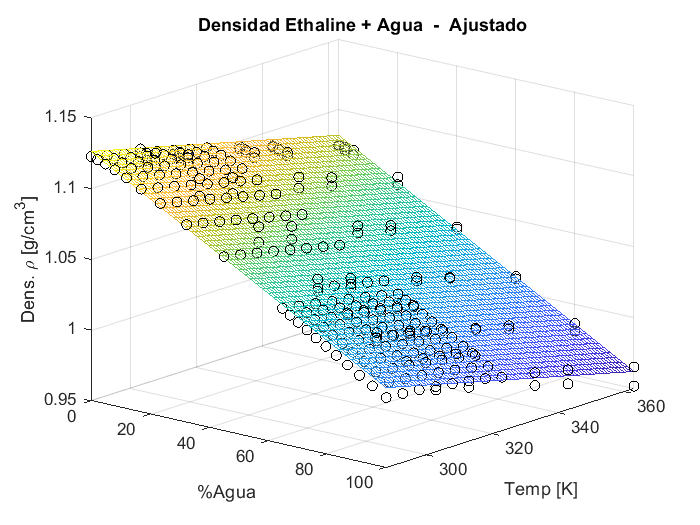

figure, plot3(Masa_H2O_Eth,Temp_Eth,Rho_Eth,'ok'); hold on,
mesh(X1fit,X2fit,Y1fit,'FaceAlpha','0.25'), hold off
title('Densidad Ethaline + Agua  -  Ajustado'), grid on,
xlabel('%Agua'), ylabel('Temp [K]'), zlabel('Dens. \rho [g/cm^3]'),
view([40 20])

**4. Analisis de residuos del conjunto de entrenamiento**

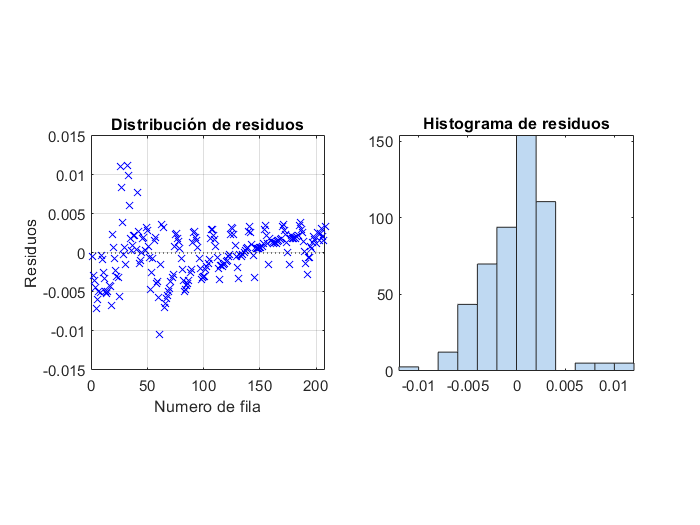

subplot(1,2,1)
plotResiduals(regresion1,'caseorder'),
title('Distribución de residuos'), xlabel('Numero de fila'),
ylabel('Residuos'), grid on, axis square
subplot(1,2,2)
plotResiduals(regresion1), title('Histograma de residuos'), axis square

El histograma muestra que los residuos están ligeramente sesgados a la derecha.

**5. Evaluación Datos de Prueba**

Grafica comparacion datos de prueba

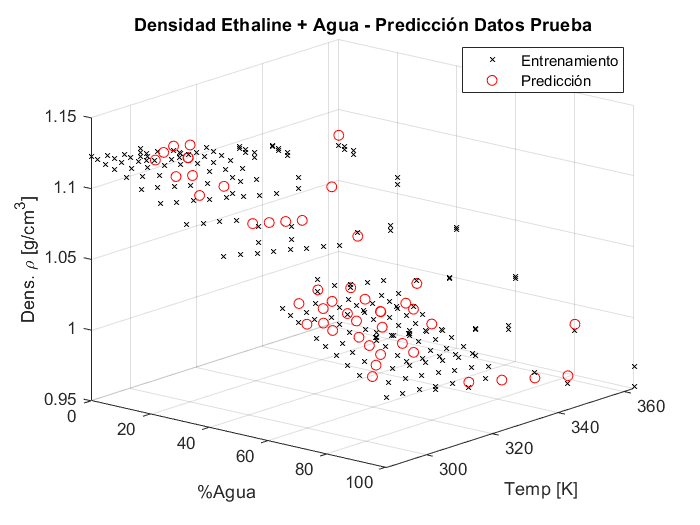

Y1_test=predict(regresion1,[Masa_H2O_Eth_test Temp_Eth_test]);
%Y1_test es la predicción con los datos de prueba
figure, plot3(Masa_H2O_Eth_train,Temp_Eth_train,Rho_Eth_train,'xk','MarkerSize',4)
hold on;
plot3(Masa_H2O_Eth_test,Temp_Eth_test,Y1_test,'or');
title('Densidad Ethaline + Agua - Predicción Datos Prueba'), grid on,
xlabel('%Agua'), ylabel('Temp [K]'), zlabel('Dens. \rho [g/cm^3]'),
legend('Entrenamiento','Predicción',"Location","best")
view([40 20])

Graficas de residuos de los datos de prueba

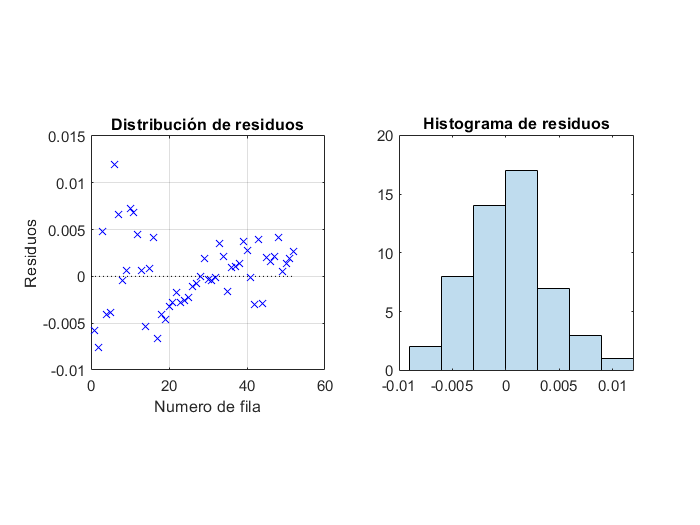

residuos_test=Rho_Eth_test-Y1_test;
subplot(1,2,1)
plot([0:length(Y1_test)],zeros*[0:length(Y1_test)],':k'), hold on,
plot(residuos_test,'xb'), title('Distribución de residuos'),
xlabel('Numero de fila'), ylabel('Residuos'),
grid on, hold off, axis square
subplot(1,2,2)
histogram(residuos_test,'FaceAlpha',0.25),
title('Histograma de residuos'), axis square